% Data with CA1 firing rate matrix on a center stem of a maze Neurons
% develop selectivity to left vs right turns over learning

% 1. Features: the firing rate matrix of the CA1 population at the center
% stem, which is (the number of cells) X (the number of trials). It has 40
% simultaneously recorded CA1 cells.

% 2. trial_label: the label for each trials, 1 is left-turn, 0 is
% right-turn.

% 3. descript: short description of the data

% The "Features" and "trial_label" have two cell arrays of data. cell array
% 1 is for early learning sessions, cell array 2 is for the late learning
% sessions. The difference in selectivity between early and late learning
% can be observed in the PC space.


% Load data
load('Example1_CA1_choice_selectivity.mat')



%------- PCA direct -----%

% Plot for early and late learning trials

%------- Early learning first -----%
learn = 1; %Early learning trials

[dim, num_data] = size(Features{learn}); % 40 neurons, 62 trials
X = Features{learn}'; 
% Here, you have P = 40 neurons/dimensions/variables
% N = 62 trials/observations/datapoints
% X is a 62x40 matrix

[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED, MU] = pca(X);

% COEFF returns 40 principal components in columns, with each PC having 40
% coefficients along original dimensions

% SCORES are the projections: Original data in 62 trials projected along
% the new 40 dimensions

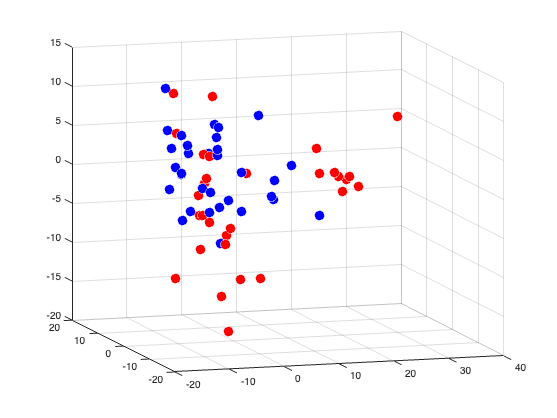


% Plot the first 3 dimensions - label left and right trials with color
figure('color','w')
title ('Early Learning')
leftidx = find(trial_label{learn} == 1);
scatter3(SCORE(leftidx,1),SCORE(leftidx,2),SCORE(leftidx,3),100,...
                    'filled','MarkerFaceColor','r',...
                        'MarkerEdgeColor','w');
hold on,
rightidx = find(trial_label{learn} == 0);
scatter3(SCORE(rightidx,1),SCORE(rightidx,2),SCORE(rightidx,3),100,...
                    'filled','MarkerFaceColor','b',...
                        'MarkerEdgeColor','w');



%------- Late learning first -----%
learn = 2; %Late learning trials

[dim, num_data] = size(Features{learn}); % 40 neurons, 61 trials
X = Features{learn}'; 
[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED, MU] = pca(X);

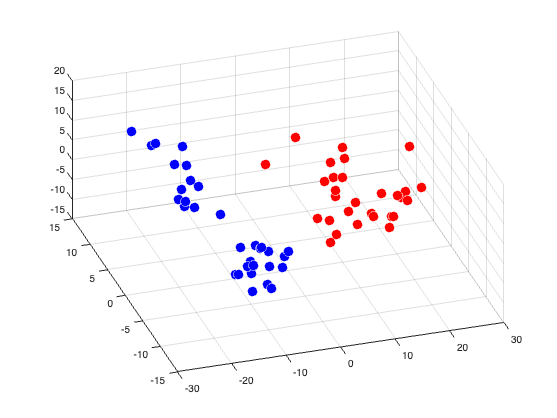


figure('color','w')
title ('Late Learning')
leftidx = find(trial_label{learn} == 1);
scatter3(SCORE(leftidx,1),SCORE(leftidx,2),SCORE(leftidx,3),100,...
                    'filled','MarkerFaceColor','r',...
                        'MarkerEdgeColor','w');
hold on,
rightidx = find(trial_label{learn} == 0);
scatter3(SCORE(rightidx,1),SCORE(rightidx,2),SCORE(rightidx,3),100,...
                    'filled','MarkerFaceColor','b',...
                        'MarkerEdgeColor','w');

       
                    


%------- PCA using svd -----%

% Plot for early and late learning trials

%------- Early learning first -----%
learn = 1; %Early learning trials
[dim, num_data] = size(Features{learn}); % 40 neurons, 62 trials
% Here, you have P = 40 neurons/dimensions/variables
% N = 62 trials/observations/datapoints

% For PCA using SVD (singular value decopmposition), center the data and
% normalize

x_temp=Features{learn}';

vector_mean = mean(Features{learn}')';
Features_center =  Features{learn} - vector_mean*ones(1,num_data);
X = Features_center'/sqrt(num_data -1);
% X in a 62x40 matrix, or NxP
[u,S,PC] = svd(X);
% PC return 40 principal components in columns, with each PC having 40
% coefficients along original dimensions

% Sort PCs in descending order. In this case, the diagonal matrix S and 
% the PCs are already in descending order

%DS = diag(S); % S is a diagonal matrix
%[DS, rindices] = sort(-1.*DS); 
%DS = -1*DS;
%V = S.*S;
%PC = PC(:,rindices);


% Project data along new PC axes
signals = PC'*Features_center;
% signals has projected data for each trial in new 40 dimensions 
% Examine the first 3 new dimensions in a plot

%---Plot-----%

% Plot projected trial data, and separately for left vs right turns
figure('color','w')
title('Early Learning')
leftidx = find(trial_label{learn} == 1);
scatter3(signals(1,leftidx),signals(2,leftidx),signals(3,leftidx),100,...
                    'filled','MarkerFaceColor','r',...
                        'MarkerEdgeColor','w');
hold on,
rightidx = find(trial_label{learn} == 0);
scatter3(signals(1,rightidx),signals(2,rightidx),signals(3,rightidx),100,...
                    'filled','MarkerFaceColor','b',...
                        'MarkerEdgeColor','w');
                    
                    

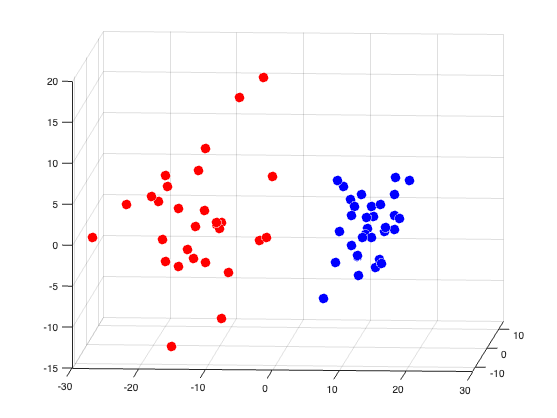

 %------- Late learning using SVD -----%  
learn = 2; %Late learning trials
[dim, num_data] = size(Features{learn}); % 40 neurons, 61 trials

vector_mean = mean(Features{learn}')';
Features_center =  Features{learn} - vector_mean*ones(1,num_data);
X = Features_center'/sqrt(num_data -1);
[u,S,PC] = svd(X);
signals = PC'*Features_center;

% Plot
figure('color','w')
title ('Late Learning')
leftidx = find(trial_label{learn} == 1);
scatter3(signals(1,leftidx),signals(2,leftidx),signals(3,leftidx),100,...
                    'filled','MarkerFaceColor','r',...
                        'MarkerEdgeColor','w');
hold on,
rightidx = find(trial_label{learn} == 0);
scatter3(signals(1,rightidx),signals(2,rightidx),signals(3,rightidx),100,...
                    'filled','MarkerFaceColor','b',...
                        'MarkerEdgeColor','w');